# Principal Component Analysis (PCA)

Lorem Ipsum

clc
clear
close all

Genero distribuzione normale di $n$ punti random con deviazione standard $\sigma$ e media $\mu$

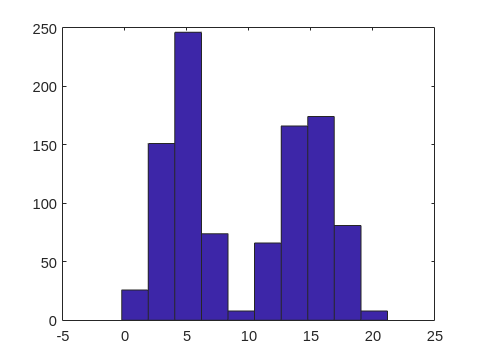

n = 500;                % numero di punti
sigma = 2;              % deviazione standard
mu = 15;                % media

% genero primo set di dati (l = 0)
data = sigma.*randn(n,2) + mu;
l = repelem(0,n,1);

% concateno secondo set di dati (l = 1)
data = [data; (sigma*0.8).*randn(n,2) + mu*0.3];
l = [l; repelem(1,n,1)];
x = data(:,1);
y = data(:,2);

% rappresento dati
hist(x)

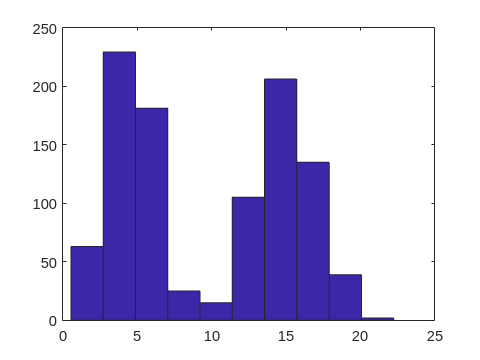

hist(y)

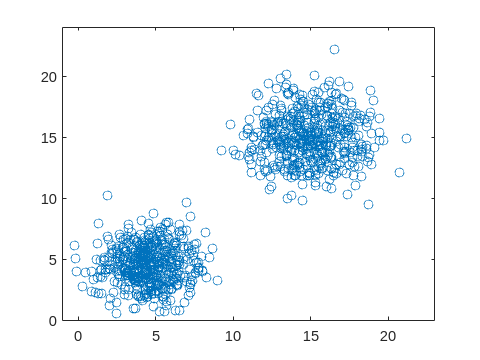


plot(x,y,'o')
xlim([floor(min(x))-1 ceil(max(x))]+1)
ylim([floor(min(y))-1 ceil(max(y))]+1)

Per filtrare le x e le y appartenenti alla prima distribuzione mi basta usare la sintassi `x(l==0)` e `y(l==0)` che sta per "prendimi le righe che rispettano la condizione `l==0`". Procedo quindi a rappresentare queste due distribuzioni

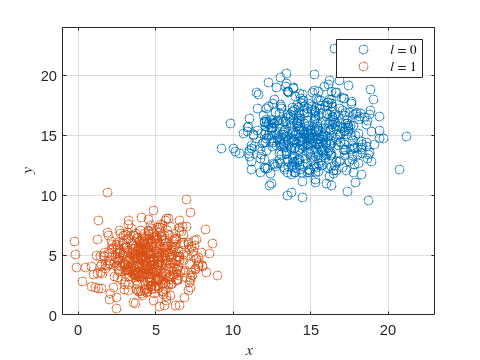

% rappresento la prima distribuzione
plot(x(l==0),y(l==0),'o')
hold on
% rappresento la seconda distribuzione
plot(x(l==1),y(l==1),'o')
hold off
xlim([floor(min(x))-1 ceil(max(x))]+1)
ylim([floor(min(y))-1 ceil(max(y))]+1)
grid on
legend("$l = 0$","$l = 1$",'Interpreter','latex')
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')

% calcolo media
xm = mean(x);
ym = mean(y);

% centro i dati
xc = x-xm;
yc = y-ym;

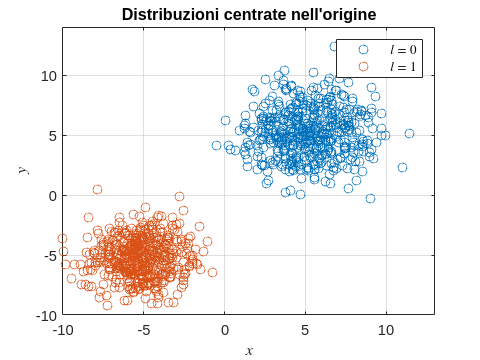

% plotto distribuzione centrata
plot(xc(l==0),yc(l==0),'o')
hold on
plot(xc(l==1),yc(l==1),'o')
hold off
xlim([floor(min(xc))-1 ceil(max(xc))]+1)
ylim([floor(min(yc))-1 ceil(max(yc))]+1)
grid on
legend("$l = 0$","$l = 1$",'Interpreter','latex')
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
title("Distribuzioni centrate nell'origine")

% esporto in md
livescript2markdown("pca.mlx","../README.md","AddMention",true)

MATLAB has experienced a low-level graphics error, and may not have drawn correctly.
Read about what you can do to prevent this issue at Resolving Low-Level Graphics Issues then restart MATLAB.
To share details of this issue with MathWorks technical support,
please include <a href="file:/home/dennisangemi/jogl.ex.7077">this file</a> with your service request.
Coverting latex to markdown is complete
README.md
Note: Related images are saved in README_images


ans = "/home/dennisangemi/Documenti/GitHub/machine-learning-for-physics/2_principal_component_analysis/README.md"